# Visual Area Size Analyses

## Humans: Initialize Variables

clear all
addpath(genpath('matlabfunctions'))
addpath(genpath('/Applications/MATLAB_TOOLBOXES'))

data_dir = ['.\Humans'];
save_folder = ['.\Graphs'];

% these numbers correspond to visual area labels (second column of roi)
allvisual_numbers=[1,2,3,4,5,6,150,151,152,153,154,50,51,52,100,101,102,103];
allvisual_labels={'V1v','V1d','V2v','V2d','V3v','V3d','hV4','VO1','VO2','PHC1','PHC2','V3A','V3B','LO1','LO2','TO1','TO2'};
allparietal_numbers=1:7; %201-207
allparietal_labels={'IPS0','IPS1','IPS2','IPS3','IPS4','IPS5','SPL1'};
allfrontal_numbers=1:2; %208-209
allfrontal_labels={'FEF','IFS'};

% these numbers correspond to color-coded grouping of brain areas in plots
EVCrois_human=1:6; EVCcolor=[0 0 0.7];
V4rois_human=7; V4color=[0.6 0 0.6];
ventralrois_human=8:11; ventralcolor=[0.6 0.1 0.1];
dorsalrois_human=12:13; dorsalcolor=[0.8 .5 0];
lateralrois_human=14:17; lateralcolor=[0.2784    0.5216    0.1451];
parietalrois_human=18:24; parietalcolor=[0 0.7 0.7];
frontalrois_human=25:26; frontalcolor=[.4 0 .4];

% concatenate all human area ROIs, labels, and colors
allrois_human = {EVCrois_human;V4rois_human;ventralrois_human;dorsalrois_human;lateralrois_human;parietalrois_human;frontalrois_human};%LGNrois};
alllabels_vd_human=[allvisual_labels, allparietal_labels, allfrontal_labels];
use_colorscale_vd_human=[repmat(EVCcolor,length(EVCrois_human),1);...
    repmat(V4color,length(V4rois_human),1);...
    repmat(ventralcolor,length(ventralrois_human),1);...
    repmat(dorsalcolor,2,1);...
    repmat(lateralcolor,length(lateralrois_human),1);...
    repmat(parietalcolor,length(parietalrois_human),1);...
    repmat(frontalcolor,length(frontalrois_human),1)];

load('allhumandata.mat')

## Humans: Calculate Averages Based on Metric

% calculate sum of retinal (removing v7), parietal, and frontal areas
for i = 1:2
    surfacearea_total{i} = humandata.retino_surfacearea_total{i} + humandata.parietal_surfacearea_total{i} + humandata.frontal_surfacearea_total{i};
    surfacearea_smoothwm{i} = [humandata.retino_surfacearea_smoothwm{i}([1:13,15:18],:);humandata.parietal_surfacearea_smoothwm{i};humandata.frontal_surfacearea_smoothwm{i}];
    surfacearea_pial{i} = [humandata.retino_surfacearea_pial{i}([1:13,15:18],:);humandata.parietal_surfacearea_pial{i};humandata.frontal_surfacearea_pial{i}];
end

% sum over hemispheres
total_surfacearea_bothhemis=surfacearea_total{1}+surfacearea_total{2};

% actual full brain surface area
total_area_cat_human = [humandata.total_size(:,1)' humandata.total_size(:,2)'];

% Make 0 sum ROIs -> NaN
for i = 1:2
    surfacearea_smoothwm{i}(surfacearea_smoothwm{i}==0)=nan;
    surfacearea_pial{i}(surfacearea_pial{i}==0)=nan;
end

% get average of white matter and pial surface area
surfacearea_avg = cellfun(@(x,y) (x+y)/2, surfacearea_smoothwm, surfacearea_pial,'UniformOutput',false);

% use this for average of WM and pial surface
SA_sumhemis_vd_human = surfacearea_avg{1} + surfacearea_avg{2};
SA_bothhemis_vd_human = surfacearea_avg;
SA_cathemis_vd_human = [surfacearea_avg{1}, surfacearea_avg{2}];

## Humans: Set Up Categories of Regions

% restructure summed hemisphere data to get area categories we want to display
V1_sumhemis_sumvd = SA_sumhemis_vd_human(1,:) + SA_sumhemis_vd_human(2,:);
V2_sumhemis_sumvd = sum(SA_sumhemis_vd_human(3:4,:),1);
V3_sumhemis_sumvd = sum(SA_sumhemis_vd_human(5:6,:),1);
V4_sumhemis_sumvd = SA_sumhemis_vd_human(7,:);

SA_sumhemis_human = [V1_sumhemis_sumvd;V2_sumhemis_sumvd;...
    V3_sumhemis_sumvd;V4_sumhemis_sumvd;SA_sumhemis_vd_human(8:end,:)];

% restructure concatenated hemisphere data to get area categories we want to display
V1_cathemis_sumvd = SA_cathemis_vd_human(1,:) + SA_cathemis_vd_human(2,:);
V2_cathemis_sumvd = sum(SA_cathemis_vd_human(3:4,:),1);
V3_cathemis_sumvd = sum(SA_cathemis_vd_human(5:6,:),1);
V4_cathemis_sumvd = SA_cathemis_vd_human(7,:);

SA_cathemis_human = [V1_cathemis_sumvd;V2_cathemis_sumvd;...
    V3_cathemis_sumvd;V4_cathemis_sumvd;SA_cathemis_vd_human(8:end,:)];

% average over broad areas for raw surface area measurements
ventral_avgregion_human = mean(SA_sumhemis_human(ventralrois_human-3,:),1);
dorsal_avgregion_human = mean(SA_sumhemis_human(dorsalrois_human-3,:),1);
lateral_avgregion_human = mean(SA_sumhemis_human(lateralrois_human-3,:),1);
parietal_avgregion_human = mean(SA_sumhemis_human(parietalrois_human-3,:),1);
frontal_avgregion_human = mean(SA_sumhemis_human(frontalrois_human-3,:),1);

SA_sumhemis_avgregion_human = [SA_sumhemis_human(1:4,:);ventral_avgregion_human;dorsal_avgregion_human;...
    lateral_avgregion_human;parietal_avgregion_human;frontal_avgregion_human];

use_colorscale_region_human=[EVCcolor;EVCcolor;EVCcolor;V4color;ventralcolor;dorsalcolor;lateralcolor;parietalcolor;frontalcolor];
use_colorscale_human=[EVCcolor;EVCcolor;EVCcolor;use_colorscale_vd_human(7:end,:)];
use_colorscale_unique_human = unique(use_colorscale_human,'stable','rows');
use_colorscale_inv_human_all = flipud(use_colorscale_vd_human);
use_colorscale_inv_human = flipud(use_colorscale_human);
use_colorscale_region_human_inv = flipud(use_colorscale_region_human);

alllabels_human = {'V1','V2','V3','hV4','VO1','VO2','PHC1','PHC2','V3A','V3B','LO1','LO2','TO1','TO2','IPS0','IPS1','IPS2','IPS3','IPS4','IPS5','SPL1','FEF','IFS'};

## Monkeys: Initialize Variables

data_dir = ['.\Monks'];
save_folder = ['.\Graphs'];

% these numbers correspond to visual area labels (second column of roi)
allvisual_numbers=[1,2,3,4,5,6,7,8,9,10,150,151,152,200,201,50,51,100,101,102,103,52,53,54,55,56];
alllabels_vd_monkey={'V1v','V1d','V2v','V2d','V3v','V3d','V4v','V4d','V4Av','V4Ad','OTd','PITv','PITd','OTS1','OTS2','V3A','DP','MT','MST','FST','V4t','CIP1','CIP2','LIP1','LIP2','LIP3'};       

% these numbers correspond to color-coded grouping of brain areas in plots
EVCrois_monkey=1:6; EVCcolor=[0.1 0.6 1];
V4rois_monkey=7:10; V4color=[1 0.2 1];
ventralrois_monkey=11:15; ventralcolor=[1 0.2 0.2];
dorsalrois_monkey=16:17; dorsalcolor=[1 .8 0];
lateralrois_monkey=18:21; lateralcolor=[0 1 0];
parietalrois_monkey=22:26; parietalcolor=[0 1 1];

% concatenate all human area ROIs, labels, and colors
allrois_monkey = {EVCrois_monkey;V4rois_monkey;ventralrois_monkey;dorsalrois_monkey;parietalrois_monkey;lateralrois_monkey};
use_colorscale_vd_monkey=[repmat(EVCcolor,length(EVCrois_monkey),1);...
    repmat(V4color,length(V4rois_monkey),1);...
    repmat(ventralcolor,length(ventralrois_monkey),1);...
    repmat(dorsalcolor,length(dorsalrois_monkey),1);...
    repmat(lateralcolor,length(lateralrois_monkey),1);...
    repmat(parietalcolor,length(parietalrois_monkey),1)];

load('allmonkeydata.mat')

## Monkeys: Calculate Averages Based on Metric

% rename areas to match human code
for i = 1:2
    surfacearea_total{i} = monkeydata.retino_surfacearea_total{i};
    surfacearea_smoothwm{i} = monkeydata.retino_surfacearea_smoothwm{i};
    surfacearea_pial{i} = monkeydata.retino_surfacearea_pial{i};
end

% sum over hemispheres
total_surfacearea_bothhemis=surfacearea_total{1}+surfacearea_total{2};

% actual full brain surface area
total_area_cat_monkey = [monkeydata.total_size(:,1)' monkeydata.total_size(:,2)'];

% Make 0 sum ROIs -> NaN
for i = 1:2
    surfacearea_smoothwm{i}(surfacearea_smoothwm{i}==0)=nan;
    surfacearea_pial{i}(surfacearea_pial{i}==0)=nan;
end

% get average of white matter and pial surface area
surfacearea_avg = cellfun(@(x,y) (x+y)/2, surfacearea_smoothwm, surfacearea_pial,'UniformOutput',false);

% use this for average of WM and pial surface
SA_sumhemis_vd_monkey = surfacearea_avg{1} + surfacearea_avg{2};
SA_bothhemis_vd_monkey = surfacearea_avg;
SA_cathemis_vd_monkey = [surfacearea_avg{1}, surfacearea_avg{2}];

## Monkeys: Set Up Categories of Regions

% restructure summed hemisphere data to get area categories we want to display
V1_sumhemis_combined = SA_sumhemis_vd_monkey(1,:) + SA_sumhemis_vd_monkey(2,:);
V2_sumhemis_combined = sum(SA_sumhemis_vd_monkey(3:4,:),1);
V3_sumhemis_combined = sum(SA_sumhemis_vd_monkey(5:6,:),1);
V4_sumhemis_combined = sum(SA_sumhemis_vd_monkey(7:8,:),1);
V4A_sumhemis_combined = sum(SA_sumhemis_vd_monkey(9:10,:),1);

SA_sumhemis_monkey = [V1_sumhemis_combined;V2_sumhemis_combined;V3_sumhemis_combined;...
    V4_sumhemis_combined;V4A_sumhemis_combined;SA_sumhemis_vd_monkey(11:end,:)];

% restructure concatenated hemisphere data to get area categories we want to display
V1_cathemis_combined = SA_cathemis_vd_monkey(1,:) + SA_cathemis_vd_monkey(2,:);
V2_cathemis_combined = sum(SA_cathemis_vd_monkey(3:4,:),1);
V3_cathemis_combined = sum(SA_cathemis_vd_monkey(5:6,:),1);
V4_cathemis_combined = sum(SA_cathemis_vd_monkey(7:8,:),1);
V4A_cathemis_combined = sum(SA_cathemis_vd_monkey(9:10,:),1);

SA_cathemis_monkey = [V1_cathemis_combined;V2_cathemis_combined;V3_cathemis_combined;...
    V4_cathemis_combined;V4A_cathemis_combined;SA_cathemis_vd_monkey(11:end,:)];

% average over broad areas for raw surface area measurements
V4_avgregion_monkey = mean(SA_sumhemis_monkey(4:5,:),1);
ventral_avgregion_monkey = mean(SA_sumhemis_monkey(ventralrois_monkey-5,:),1);
dorsal_avgregion_monkey = mean(SA_sumhemis_monkey(dorsalrois_monkey-5,:),1);
lateral_avgregion_monkey = mean(SA_sumhemis_monkey(lateralrois_monkey-5,:),1);
parietal_avgregion_monkey = mean(SA_sumhemis_monkey(parietalrois_monkey-5,:),1);

SA_sumhemis_avgregion_monkey = [SA_sumhemis_monkey(1:3,:);V4_avgregion_monkey;ventral_avgregion_monkey;...
    dorsal_avgregion_monkey;lateral_avgregion_monkey;parietal_avgregion_monkey];

use_colorscale_region_monkey=[EVCcolor;EVCcolor;EVCcolor;V4color;ventralcolor;dorsalcolor;lateralcolor;parietalcolor;frontalcolor];
use_colorscale_monkey=[EVCcolor;EVCcolor;EVCcolor;V4color;V4color;use_colorscale_vd_monkey(11:end,:)];
use_colorscale_unique_monkey = unique(use_colorscale_monkey,'stable','rows');
use_colorscale_inv_monkey_all = flipud(use_colorscale_vd_monkey);
use_colorscale_inv_monkey = flipud(use_colorscale_monkey);
use_colorscale_region_monkey_inv = flipud(use_colorscale_region_monkey);

alllabels_monkey = {'V1','V2','V3','V4','V4A','OTd','PITv','PITd','OTS1','OTS2','V3A','DP','MT','MST','FST','V4t','CIP1','CIP2','LIP1','LIP2','LIP3'};       

alllabels_avgregion = {'V1','V2','V3','V4','Ventral','Dorsal','Lateral','Parietal'};
alllabels_double = {'V1','V1','V2','V2','V3','V3','V4','V4','Ventral','Ventral','Dorsal','Dorsal','Lateral','Lateral','Parietal','Parietal','Frontal'};

## Fig 2A: Plot Raw Surface Area Human

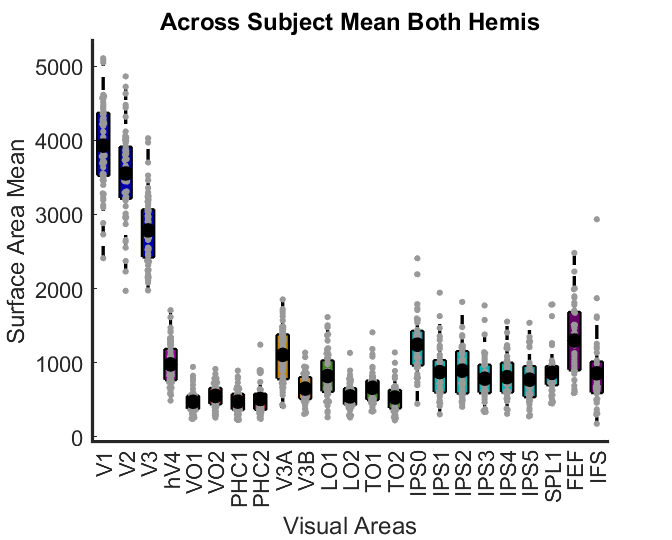

figure
hold on
h=boxplot(SA_sumhemis_human','notch','off','colors',[0 0 0],'symbol','');
set(h,{'linew'},{2})
h = findobj(gca,'Tag','Box');
for j=1:length(h)
    patch(get(h(j),'XData'),get(h(j),'YData'),(use_colorscale_inv_human_all(j,:)),'FaceAlpha',1);
end
hold on
plotSpread(SA_sumhemis_human','distributionColors',use_colorscale_vd_human(4:end,:)*0+[.6 .6 .6],'spreadWidth',.5)
plot(nanmean(SA_sumhemis_human'),'k.','MarkerSize',30);
xlim([0.5 size(SA_sumhemis_human,1)+.5])
yticks(0:1000:5000)
ax = gca;
ax.XRuler.Axle.LineWidth = 2;
ax.YRuler.Axle.LineWidth = 2;
box off
ax.XAxis.TickLength = [0 0];
ax.FontSize = 13;
set(gca,'xtick',[1:length(alllabels_human)],'xticklabel', alllabels_human);
xlabel('Visual Areas');
ylabel('Surface Area Mean');
title('Across Subject Mean Both Hemis')
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, .35, .45]);

## Fig 2B: Plot Raw Surface Area Monkey

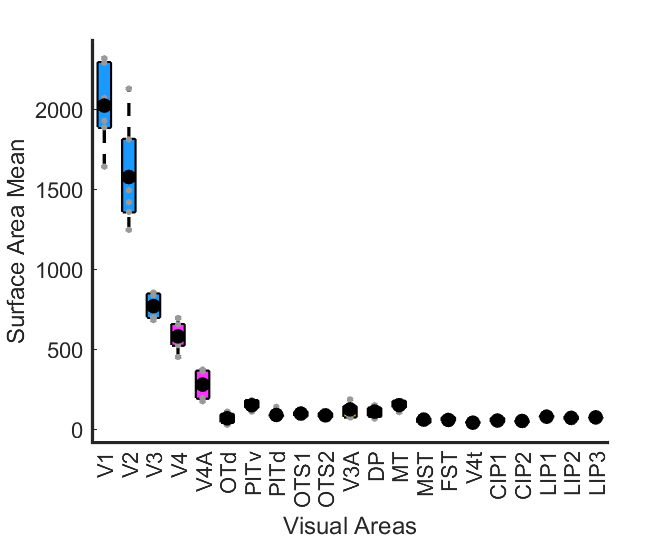

figure
hold on
h=boxplot(SA_sumhemis_monkey','notch','off','colors',[0 0 0],'symbol','');
set(h,{'linew'},{2})
h = findobj(gca,'Tag','Box');
for j=1:length(h)
    patch(get(h(j),'XData'),get(h(j),'YData'),(use_colorscale_inv_monkey(j,:)),'FaceAlpha',1);
end
hold on
plotSpread(SA_sumhemis_monkey','distributionColors',use_colorscale_monkey*0+[.6 .6 .6],'spreadWidth',.5)
plot(nanmean(SA_sumhemis_monkey'),'k.','MarkerSize',30);
xlim([0.5 size(SA_sumhemis_monkey,1)+.5])
yticks(0:500:2500)
ax = gca;
ax.XRuler.Axle.LineWidth = 2;
ax.YRuler.Axle.LineWidth = 2;
box off
ax.XAxis.TickLength = [0 0];
ax.FontSize = 13;
set(gca,'xtick',[1:length(alllabels_monkey)],'xticklabel', alllabels_monkey);
xlabel('Visual Areas');
ylabel('Surface Area Mean');
% title('Across Subject Mean Both Hemis')
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, .35, .45]);

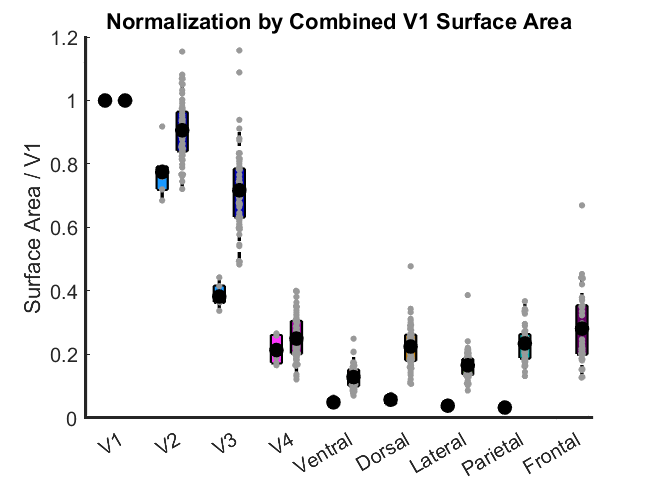

%normalize human by v1
normv1_sumhemis_vd_human = SA_sumhemis_human./V1_sumhemis_sumvd;

% average over broad regions for surface area measurements relative to V1
normventral_human = mean(normv1_sumhemis_vd_human(ventralrois_human-3,:),1);
normdorsal_human = mean(normv1_sumhemis_vd_human(dorsalrois_human-3,:),1);
normlateral_human = mean(normv1_sumhemis_vd_human(lateralrois_human-3,:),1);
normparietal_human = mean(normv1_sumhemis_vd_human(parietalrois_human-3,:),1);
normfrontal_human = mean(normv1_sumhemis_vd_human(frontalrois_human-3,:),1);

normv1_combined_human = [normv1_sumhemis_vd_human(1:4,:);normventral_human;normdorsal_human;...
    normlateral_human;normparietal_human;normfrontal_human];

%combined monkey by V1
normv1_sumhemis_vd_monkey = SA_sumhemis_monkey./V1_sumhemis_combined;

% average over broad regions for surface area measurements relative to V1
normV4_monkey = mean(normv1_sumhemis_vd_monkey(4:5,:),1);
normventral_monkey = mean(normv1_sumhemis_vd_monkey(ventralrois_monkey-5,:),1);
normdorsal_monkey = mean(normv1_sumhemis_vd_monkey(dorsalrois_monkey-5,:),1);
normlateral_monkey = mean(normv1_sumhemis_vd_monkey(lateralrois_monkey-5,:),1);
normparietal_monkey = mean(normv1_sumhemis_vd_monkey(parietalrois_monkey-5,:),1);

normv1_combined_monkey = [normv1_sumhemis_vd_monkey(1:3,:);normV4_monkey;normventral_monkey;...
    normdorsal_monkey;normlateral_monkey;normparietal_monkey];

% pad array with nan to get the same size as humans
addnanmonkey = padarray(normv1_combined_monkey,[1 size(normv1_combined_human,2) - size(normv1_combined_monkey,2)],nan,'post');
concat_data = [];
concat_colorscale = [];
for i = 1:size(normv1_combined_human,1)
    concat_data = [concat_data; addnanmonkey(i,:); normv1_combined_human(i,:)];
    concat_colorscale = [concat_colorscale;use_colorscale_region_human_inv(i,:);use_colorscale_region_monkey_inv(i,:)];
end

% set groupings by species and areas to use factorgap in boxplot
g1 = sort([1:9,1:9]);
g2 = repmat(1:2,[1,9]);

figure('Renderer', 'painters', 'Position', [10 10 1500 500]);
hold on
h1=boxplot(concat_data',[g1' g2'],'factorgap',5,'colors',[0 0 0],'symbol','');
set(h1,{'linew'},{2})
h1 = findobj(gca,'Tag','Box');
for j=1:size(concat_data,1)
   % have to extract x values from boxplot in order to set xlabels
   xdat{j} = get(h1(j),'XData');
   xd(j) = (xdat{j}(3)+xdat{j}(2))/2;
   patch(get(h1(j),'XData'),get(h1(j),'YData'),concat_colorscale(j,:),'FaceAlpha',1);
end

plotSpread(concat_data','xValues',fliplr(xd),'distributionColors',concat_colorscale*0+[.6 .6 .6],'spreadWidth',.5)
plot(fliplr(xd),nanmean(concat_data'),'k.','MarkerSize',30);

% take average of x values for each area to put xticklabel in the middle
xt = [];
for i = 1:length(xd)/2
    xt(i) = (xd(2*i-1) + xd(2*i))/2;
end

ax = gca;
ax.XRuler.Axle.LineWidth = 2;
ax.YRuler.Axle.LineWidth = 2;
box off
ax.XAxis.TickLength = [0 0];
set(gca,'xtick',fliplr(xt),'xticklabel', alllabels_double(1:2:end),'fontsize',12);
% xlabel('Visual Areas');
ylabel('Surface Area / V1');
title('Normalization by Combined V1 Surface Area')
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, .35, .45]);
ylim([0 1.2])

## Fig 3: Plot Cross-hemisphere Correlations - Normalized

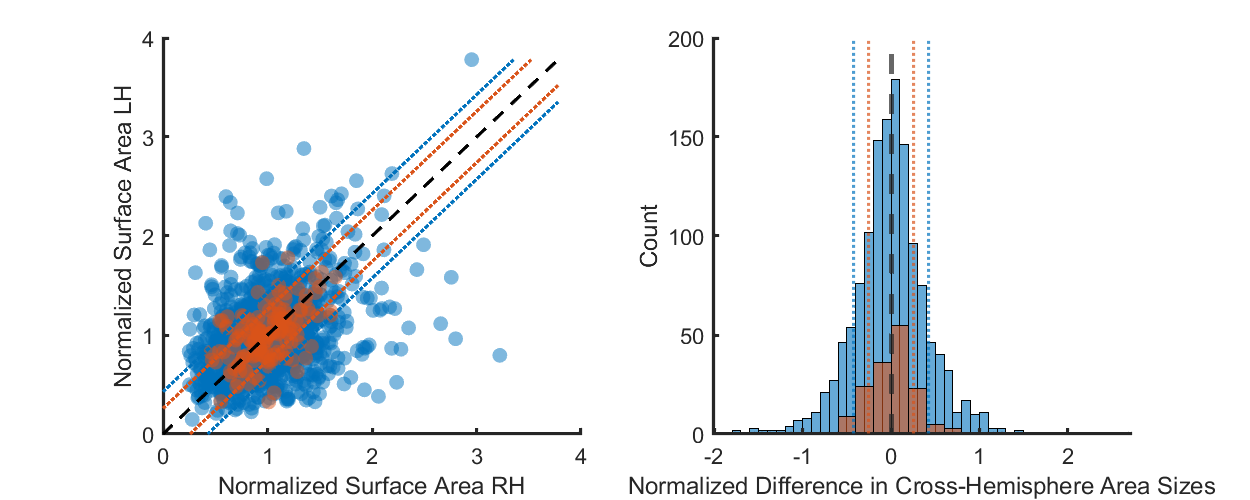

surfacearea_human_norm{1} = SA_bothhemis_vd_human{1} ./ mean(SA_bothhemis_vd_human{1},2,'omitnan');
surfacearea_human_norm{2} = SA_bothhemis_vd_human{2} ./ mean(SA_bothhemis_vd_human{2},2,'omitnan');

surfacearea_monkey_norm{1} = SA_bothhemis_vd_monkey{1} ./ mean(SA_bothhemis_vd_monkey{1},2,'omitnan');
surfacearea_monkey_norm{2} = SA_bothhemis_vd_monkey{2} ./ mean(SA_bothhemis_vd_monkey{2},2,'omitnan');
humanvar = var(surfacearea_human_norm{1}(:)-surfacearea_human_norm{2}(:),'omitnan');
humanstd = std(surfacearea_human_norm{1}(:)-surfacearea_human_norm{2}(:),'omitnan');
monkvar = var(surfacearea_monkey_norm{1}(:)-surfacearea_monkey_norm{2}(:),'omitnan');
monkstd = std(surfacearea_monkey_norm{1}(:)-surfacearea_monkey_norm{2}(:),'omitnan');

data1 = surfacearea_human_norm{1}(:)-surfacearea_human_norm{2}(:);
data2 = surfacearea_monkey_norm{1}(:)-surfacearea_monkey_norm{2}(:);
include = ~isnan(data1);data1 = data1(include);
include = ~isnan(data2);data2 = data2(include);
[h,p] = vartest2(data1, data2);
% disp([h, p])

figure('Renderer', 'painters', 'Position', [10 10 1000 400]);
subplot(1,2,1)
s1 = scatter(surfacearea_human_norm{1}(:),surfacearea_human_norm{2}(:),80,'filled');
s1.MarkerFaceAlpha = 0.5;
hold on;
s2 = scatter(surfacearea_monkey_norm{1}(:),surfacearea_monkey_norm{2}(:),80,'filled');
s2.MarkerFaceAlpha = 0.5;
max_value=max([max(surfacearea_human_norm{1}(:)),max(surfacearea_human_norm{2}(:))]);
min_value=floor([min(surfacearea_human_norm{1}(:)),min(surfacearea_human_norm{2}(:))]);
plot([min_value, max_value],[min_value,max_value],'--k','LineWidth',2)
plot([min_value, max_value-humanstd],[min_value+humanstd,max_value],':','Color',[0 0.4470 0.7410],'LineWidth',2)
plot([min_value+humanstd, max_value],[min_value,max_value-humanstd],':','Color',[0 0.4470 0.7410],'LineWidth',2)
plot([min_value, max_value-monkstd],[min_value+monkstd,max_value],':','Color',[0.8500 0.3250 0.0980],'LineWidth',2)
plot([min_value+monkstd, max_value],[min_value,max_value-monkstd],':','Color',[0.8500 0.3250 0.0980],'LineWidth',2)
xlabel('Normalized Surface Area RH')
ylabel('Normalized Surface Area LH')
% title(['Two Sample F Test: p = ',num2str(p)])
xticks(0:4)
yticks(0:4)
ax = gca;
ax.XAxis.LineWidth = 2;
ax.YAxis.LineWidth = 2;
ax.FontSize = 13;

subplot(1,2,2)
% figure('Renderer', 'painters', 'Position', [10 10 600 500]);
histogram((surfacearea_human_norm{1}(:)-surfacearea_human_norm{2}(:)));
hold on;
histogram((surfacearea_monkey_norm{1}(:)-surfacearea_monkey_norm{2}(:)));
xline(0,'--','linewidth',3)
xline(humanstd,':','Color',[0 0.4470 0.7410],'LineWidth',2)
xline(-humanstd,':','Color',[0 0.4470 0.7410],'LineWidth',2)
xline(monkstd,':','Color',[0.8500 0.3250 0.0980],'LineWidth',2)
xline(-monkstd,':','Color',[0.8500 0.3250 0.0980],'LineWidth',2)
box off
xlabel('Normalized Difference in Cross-Hemisphere Area Sizes')
ylabel('Count')
% legend('Humans','Monkeys')
% title(['Two Sample F Test: p = ',num2str(p)])
xticks(-2:2)
yticks(0:50:200)
ax = gca;
ax.XAxis.LineWidth = 2;
ax.YAxis.LineWidth = 2;
ax.FontSize = 13;

## Fig 3: Plot Cross-hemisphere Correlations - Resampling with same n

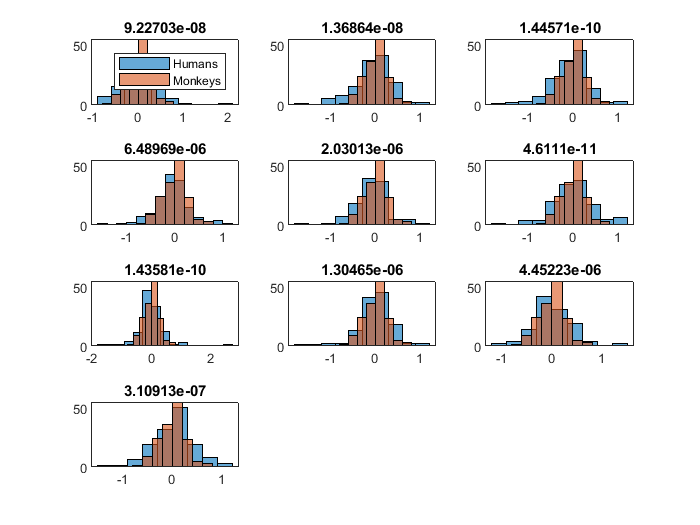

fulldata1 = surfacearea_human_norm{1} - surfacearea_human_norm{2};
fulldata2 = surfacearea_monkey_norm{1} - surfacearea_monkey_norm{2};

figure();
tiledlayout('flow')
for i = 1:10
    y = randsample(size(fulldata1,2),size(fulldata2,2));
    sampled_data = fulldata1(:,y);
    
    alldata1 = sampled_data(:);
    alldata2 = fulldata2(:);
    
    include = ~isnan(alldata1);alldata1 = alldata1(include);
    include = ~isnan(alldata2);alldata2 = alldata2(include);
    [h,p] = vartest2(alldata1, alldata2);
    
    nexttile;
    histogram(alldata1)
    hold on;
    histogram(alldata2)
    if i == 1
        legend('Humans','Monkeys')
    end
    title(p)
end

## Fig 4 A&B: Correlation Matrix Across All Areas - Human & Monkey

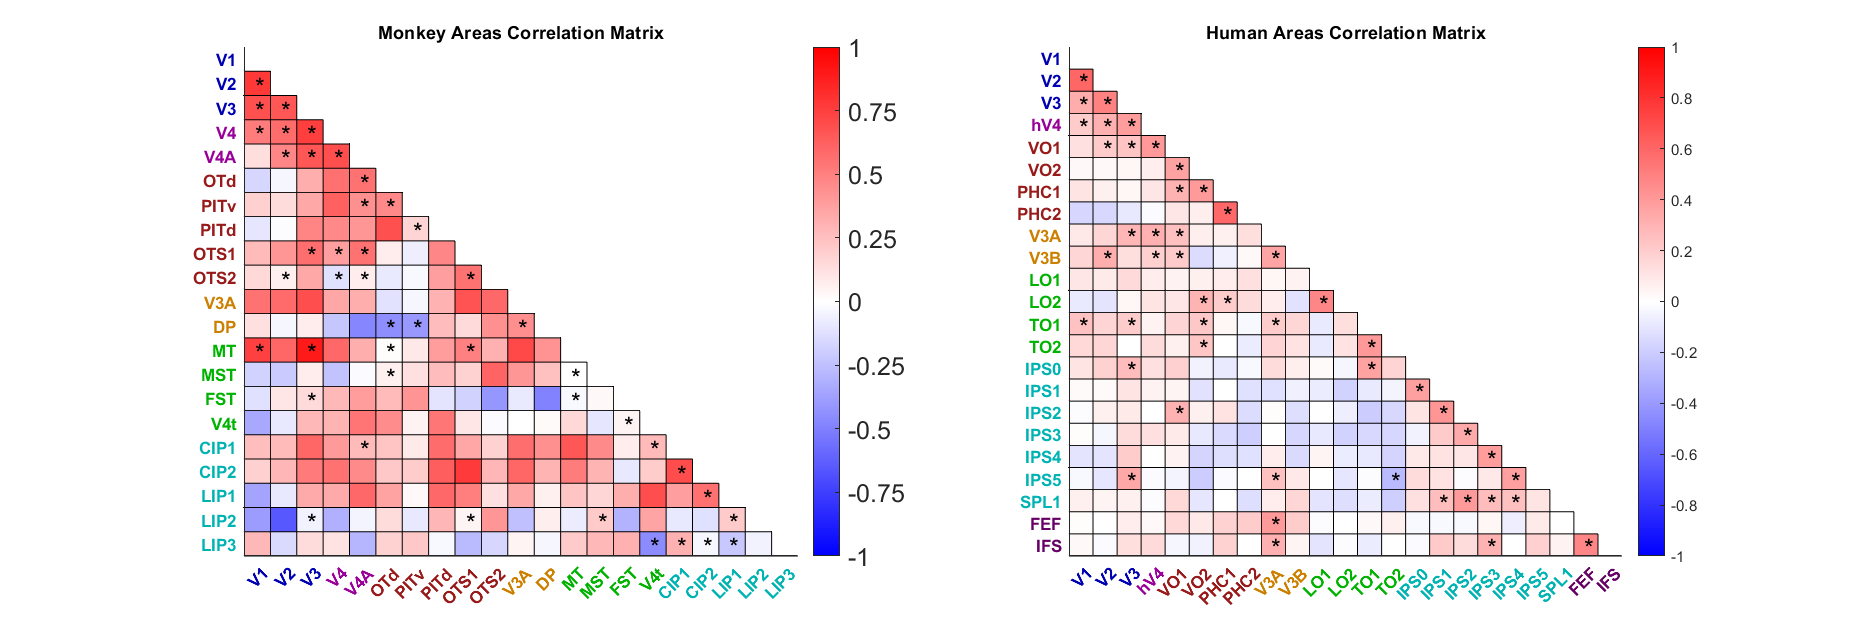

all_area_corr_human = zeros(length(alllabels_human),length(alllabels_human));
all_area_pval_human = zeros(length(alllabels_human),length(alllabels_human));
for i = 1:length(alllabels_human)
    for j = 1:length(alllabels_human)
        include = ~isnan(SA_cathemis_human(i,:)) & ~isnan(SA_cathemis_human(j,:));
        [r,p] = corr(SA_cathemis_human(i,include)',SA_cathemis_human(j,include)');
        all_area_pval_human(i,j) = p;
        all_area_corr_human(i,j) = r;
    end
end

all_area_corr_monkey = zeros(length(alllabels_monkey),length(alllabels_monkey));
all_area_pval_monkey = zeros(length(alllabels_monkey),length(alllabels_monkey));
for i = 1:length(alllabels_monkey)
    for j = 1:length(alllabels_monkey)
        include = ~isnan(SA_cathemis_monkey(i,:)) & ~isnan(SA_cathemis_monkey(j,:));
        [r,p] = corr(SA_cathemis_monkey(i,include)',SA_cathemis_monkey(j,include)');
        all_area_pval_monkey(i,j) = p;
        all_area_corr_monkey(i,j) = r;
    end
end

EVCcolor=[0 0 0.7];
V4color=[0.6 0 0.6];
ventralcolor=[0.6 0.1 0.1];
dorsalcolor=[0.8 .5 0];
lateralcolor=[0 0.7 0];
parietalcolor=[0 0.7 0.7];
frontalcolor=[.4 0 .4];

figure('Renderer', 'painters', 'Position', [10 10 1500 500]);
subplot(1,2,2)
Z = ones(size(all_area_corr_human,1), size(all_area_corr_human,2), 3);  %black background
image(Z);
hold on;
lower_tri = tril(all_area_corr_human);
lower_tri(1:length(lower_tri)+1:end) = 0;
p_tri = tril(all_area_pval_human);
p_tri(p_tri == 0) = 1;
p_tri(1:length(p_tri)+1:end) = 1;
alphadata = double(lower_tri ~= 0);

h1 = imagesc(all_area_corr_human);
h1.AlphaData = alphadata;
% hold off
for i = 1:size(all_area_corr_human,1)
    for j = 1:size(all_area_corr_human,2)
        if p_tri(j,i)<0.05
            text(i-0.1,j+0.1,'*','FontSize',15)
        end
        if j < length(all_area_corr_human)
        plot([j+0.5 j+0.5],[j+0.5 length(all_area_corr_human)+0.5],'k')
        end
    end
    plot([i+0.5 0],[i+0.5 i+0.5],'k')
end
Xticklabels_new = cell(size(alllabels_human));
Yticklabels_new = cell(size(alllabels_human));
for i = 1:3
    Xticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_human{i},'}'], EVCcolor);
    Yticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_human{i},'}'], EVCcolor);
end
for i = 4
    Xticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_human{i},'}'], V4color);
    Yticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_human{i},'}'], V4color);
end
for i = 5:8
    Xticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_human{i},'}'], ventralcolor);
    Yticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_human{i},'}'], ventralcolor);
end
for i = 9:10
    Xticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_human{i},'}'], dorsalcolor);
    Yticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_human{i},'}'], dorsalcolor);
end
for i = 11:14
    Xticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_human{i},'}'], lateralcolor);
    Yticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_human{i},'}'], lateralcolor);
end
for i = 15:21
    Xticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_human{i},'}'], parietalcolor);
    Yticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_human{i},'}'], parietalcolor);
end
for i = 22:23
    Xticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_human{i},'}'], frontalcolor);
    Yticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_human{i},'}'], frontalcolor);
end

ax = gca;
set(ax, 'XTick',1:length(alllabels_human),'XTickLabel',Xticklabels_new)
set(ax, 'YTick',1:length(alllabels_human),'YTickLabel',Yticklabels_new)
% set(ax,'xaxisLocation','top')
box off;
ax.XAxis.TickLength = [0 0];
ax.YAxis.TickLength = [0 0];

colormap(redblue);c = colorbar;caxis([-1 1]);
title('Human Areas Correlation Matrix')

subplot(1,2,1);
Z = ones(size(all_area_corr_monkey,1), size(all_area_corr_monkey,2), 3);  %black background
image(Z);
hold on;
lower_tri = tril(all_area_corr_monkey);
lower_tri(1:length(lower_tri)+1:end) = 0;
alphadata = double(lower_tri ~= 0);
p_tri = tril(all_area_pval_human);
p_tri(p_tri == 0) = 1;
p_tri(1:length(p_tri)+1:end) = 1;

h2 = imagesc(all_area_corr_monkey);
h2.AlphaData = alphadata;
% hold off
for i = 1:size(all_area_corr_monkey,1)
    for j = 1:size(all_area_corr_monkey,2)
        if p_tri(j,i)<0.05
            text(i-0.1,j+0.1,'*','FontSize',15)
        end
        if j < length(all_area_corr_monkey)
        plot([j+0.5 j+0.5],[j+0.5 length(all_area_corr_monkey)+0.5],'k')
        end
    end
    plot([i+0.5 0],[i+0.5 i+0.5],'k')    
end

Xticklabels_new = cell(size(alllabels_monkey));
Yticklabels_new = cell(size(alllabels_monkey));
for i = 1:3
    Xticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_monkey{i},'}'], EVCcolor);
    Yticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_monkey{i},'}'], EVCcolor);
end
for i = 4:5
    Xticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_monkey{i},'}'], V4color);
    Yticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_monkey{i},'}'], V4color);
end
for i = 6:10
    Xticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_monkey{i},'}'], ventralcolor);
    Yticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_monkey{i},'}'], ventralcolor);
end
for i = 11:12
    Xticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_monkey{i},'}'], dorsalcolor);
    Yticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_monkey{i},'}'], dorsalcolor);
end
for i = 13:16
    Xticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_monkey{i},'}'], lateralcolor);
    Yticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_monkey{i},'}'], lateralcolor);
end
for i = 17:21
    Xticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_monkey{i},'}'], parietalcolor);
    Yticklabels_new{i} = sprintf(['\\color[rgb]{%f, %f, %f} \\bf{', alllabels_monkey{i},'}'], parietalcolor);
end
ax = gca;
set(ax, 'XTick',1:length(alllabels_monkey),'XTickLabel',Xticklabels_new)
set(ax, 'YTick',1:length(alllabels_monkey),'YTickLabel',Yticklabels_new)
box off;
ax.XAxis.TickLength = [0 0];
ax.YAxis.TickLength = [0 0];
% set(ax,'xaxisLocation','top')
colormap(redblue);c = colorbar;caxis([-1 1]);c.Ticks = -1:0.25:1;c.FontSize = 15;

title('Monkey Areas Correlation Matrix')

## Fig 4C: Correlations of visual areas with V1

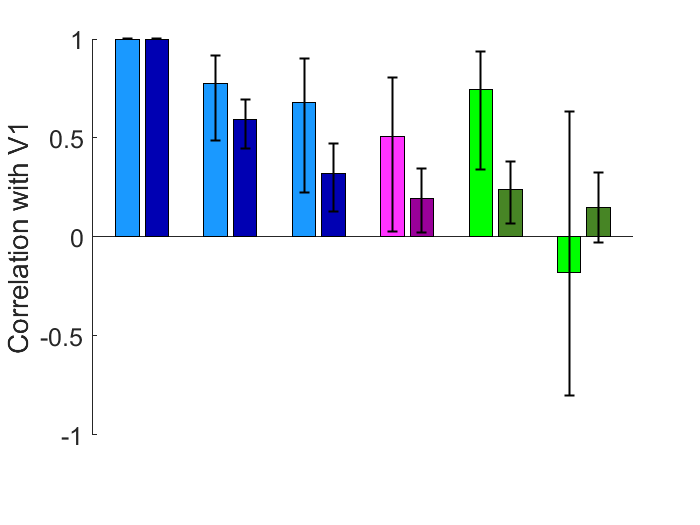

% should probably do some bootstrapping here
all_area_corr_human = zeros(length(alllabels_human),length(alllabels_human));
all_area_pval_human = zeros(length(alllabels_human),length(alllabels_human));
stats_human = zeros(length(alllabels_human),length(alllabels_human),2);
for i = 1:length(alllabels_human)
    for j = 1:length(alllabels_human)
        include = ~isnan(SA_cathemis_human(i,:)) & ~isnan(SA_cathemis_human(j,:));
        [r,p] = corr(SA_cathemis_human(i,include)',SA_cathemis_human(j,include)');
        temp = bootci(1000,@corr,[SA_cathemis_human(i,include)',SA_cathemis_human(j,include)']);
        stats_human(i,j,:) = temp(:,1,2);
        all_area_pval_human(i,j) = p;
        all_area_corr_human(i,j) = r;
    end
end

all_area_corr_monkey = zeros(length(alllabels_monkey),length(alllabels_monkey));
all_area_pval_monkey = zeros(length(alllabels_monkey),length(alllabels_monkey));
stats_monkey = zeros(length(alllabels_monkey),length(alllabels_monkey),2);
for i = 1:length(alllabels_monkey)
    for j = 1:length(alllabels_monkey)
        include = ~isnan(SA_cathemis_monkey(i,:)) & ~isnan(SA_cathemis_monkey(j,:));
        [r,p] = corr(SA_cathemis_monkey(i,include)',SA_cathemis_monkey(j,include)');
        temp = bootci(1000,@corr,[SA_cathemis_monkey(i,include)',SA_cathemis_monkey(j,include)']);
        stats_monkey(i,j,:) = temp(:,1,2);
        all_area_pval_monkey(i,j) = p;
        all_area_corr_monkey(i,j) = r;
    end
end

xlab = {'V1','V2','V3','V4','TO1/MT','TO2/MST'};
h_idx = [1:4,13,14];m_idx = [1:4,13,14];
hx = 2:3:3*6+1;mx = 1:3:3*6;
all_area_corr = [all_area_corr_human(h_idx,1), all_area_corr_monkey(m_idx,1)];
h_color = use_colorscale_human(h_idx,:);
m_color = use_colorscale_monkey(m_idx,:);

figure;hold on;
for i = 1:length(h_idx)
    bar(hx(i),all_area_corr_human(h_idx(i),1),'FaceColor',h_color(i,:));
    errorbar(hx(i),all_area_corr_human(h_idx(i),1),all_area_corr_human(h_idx(i),1)-stats_human(h_idx(i),1,1),stats_human(h_idx(i),1,2)-all_area_corr_human(h_idx(i),1),'k','LineWidth',1.2)
end
for i = 1:length(m_idx)
    bar(mx(i),all_area_corr_monkey(m_idx(i),1),'FaceColor',m_color(i,:));
    errorbar(mx(i),all_area_corr_monkey(m_idx(i),1),all_area_corr_monkey(m_idx(i),1)-stats_monkey(m_idx(i),1,1),stats_monkey(m_idx(i),1,2)-all_area_corr_monkey(m_idx(i),1),'k','LineWidth',1.2)
end
xticks(1.5:3:3*7)
xticklabels(xlab)
ax = gca;
ax.XAxis.Visible = 'off';
ax.FontSize = 15;
ylabel('Correlation with V1')
box off

## Supp. Table 1: Area sizes - raw and normalized to V1

array_labels = {'Mean','SE','Min','Max','Mean Norm','SE Norm','Min Norm','Max Norm'};

% Human values
normv1_cathemis_human = SA_cathemis_human./SA_cathemis_human(1,:);

array_of_values_human = nan(size(SA_cathemis_human,1),8);
array_of_values_human(:,1) = mean(SA_cathemis_human,2,'omitnan');
array_of_values_human(:,2) = std(SA_cathemis_human,[],2,'omitnan')/sqrt(size(SA_cathemis_human,2));
array_of_values_human(:,3) = min(SA_cathemis_human,[],2,'omitnan');
array_of_values_human(:,4) = max(SA_cathemis_human,[],2,'omitnan');

array_of_values_human(:,5) = mean(normv1_cathemis_human,2,'omitnan');
array_of_values_human(:,6) = std(normv1_cathemis_human,[],2,'omitnan')/sqrt(size(normv1_cathemis_human,2));
array_of_values_human(:,7) = min(normv1_cathemis_human,[],2,'omitnan');
array_of_values_human(:,8) = max(normv1_cathemis_human,[],2,'omitnan');
array_of_values_human(:,1:4) = round(array_of_values_human(:,1:4),2);
array_of_values_human(:,5:8) = round(array_of_values_human(:,5:8),4);

table_of_values_human = array2table(array_of_values_human,'VariableNames',array_labels,'RowNames',alllabels_human);

% Monkey values
normv1_cathemis_monkey = SA_cathemis_monkey./SA_cathemis_monkey(1,:);

array_of_values_monkey = nan(size(SA_cathemis_monkey,1),8);
array_of_values_monkey(:,1) = mean(SA_cathemis_monkey,2,'omitnan');
array_of_values_monkey(:,2) = std(SA_cathemis_monkey,[],2,'omitnan')/sqrt(size(SA_cathemis_monkey,2));
array_of_values_monkey(:,3) = min(SA_cathemis_monkey,[],2,'omitnan');
array_of_values_monkey(:,4) = max(SA_cathemis_monkey,[],2,'omitnan');

array_of_values_monkey(:,5) = mean(normv1_cathemis_monkey,2,'omitnan');
array_of_values_monkey(:,6) = std(normv1_cathemis_monkey,[],2,'omitnan')/sqrt(size(normv1_cathemis_monkey,2));
array_of_values_monkey(:,7) = min(normv1_cathemis_monkey,[],2,'omitnan');
array_of_values_monkey(:,8) = max(normv1_cathemis_monkey,[],2,'omitnan');
array_of_values_monkey(:,1:4) = round(array_of_values_monkey(:,1:4),2);
array_of_values_monkey(:,5:8) = round(array_of_values_monkey(:,5:8),4);

table_of_values_monkey = array2table(array_of_values_monkey,'VariableNames',array_labels,'RowNames',alllabels_monkey);

## Supplementary Fig: Plot Cross-hemisphere Correlations

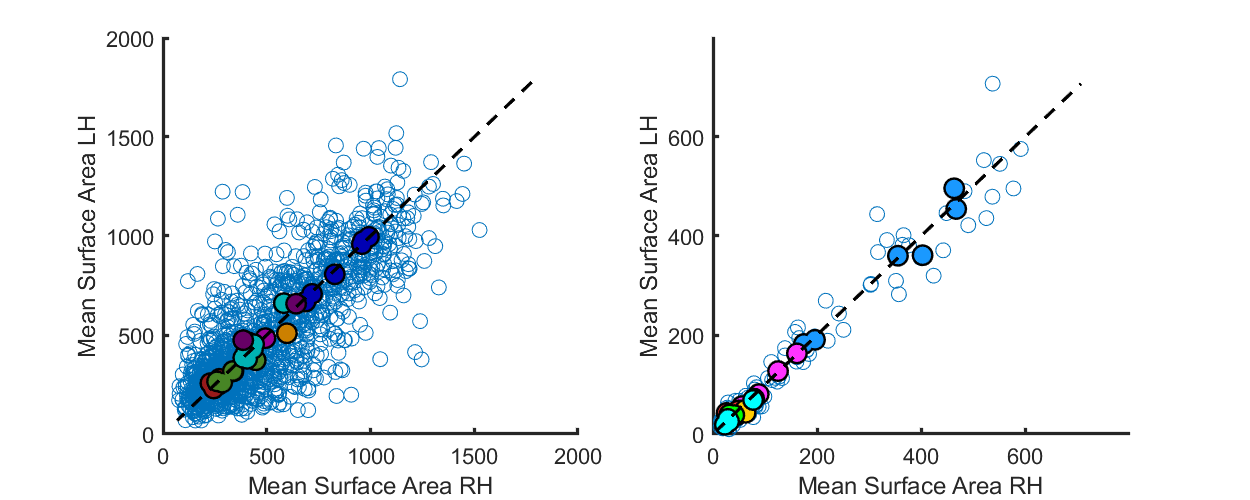

figure('Renderer', 'painters', 'Position', [10 10 1000 400])
subplot(1,2,1)
scatter(SA_bothhemis_vd_human{1}(:),SA_bothhemis_vd_human{2}(:),80);
hold on
for rr = 1:length(allrois_human)
    plot(nanmean(SA_bothhemis_vd_human{1}(allrois_human{rr},:),2),nanmean(SA_bothhemis_vd_human{2}(allrois_human{rr},:),2),'.k','MarkerSize',45);
    plot(nanmean(SA_bothhemis_vd_human{1}(allrois_human{rr},:),2),nanmean(SA_bothhemis_vd_human{2}(allrois_human{rr},:),2),'.','Color',use_colorscale_unique_human(rr,:),'MarkerSize',35);
end
max_value=max([max(SA_bothhemis_vd_human{1}(:)),max(SA_bothhemis_vd_human{2}(:))]);
min_value=floor([min(SA_bothhemis_vd_human{1}(:)),min(SA_bothhemis_vd_human{2}(:))]);
plot([min_value, max_value],[min_value,max_value],'--k','LineWidth',2)
xlabel('Mean Surface Area RH');
ylabel('Mean Surface Area LH');
xticks(0:500:2000)
yticks(0:500:2000)
set(gca,'FontSize',13)
set(gca,'linewidth',2)
% set(gca,'XTick',[])
% set(gca,'YTick',[])
% title('Human Cross-Hemisphere Surface Area Correlation')


subplot(1,2,2)
scatter(SA_bothhemis_vd_monkey{1}(:),SA_bothhemis_vd_monkey{2}(:),80);
hold on
for rr = 1:length(allrois_monkey)
    plot(nanmean(SA_bothhemis_vd_monkey{1}(allrois_monkey{rr},:),2),nanmean(SA_bothhemis_vd_monkey{2}(allrois_monkey{rr},:),2),'.k','MarkerSize',45);
    plot(nanmean(SA_bothhemis_vd_monkey{1}(allrois_monkey{rr},:),2),nanmean(SA_bothhemis_vd_monkey{2}(allrois_monkey{rr},:),2),'.','Color',use_colorscale_unique_monkey(rr,:),'MarkerSize',35);
end
max_value=max([max(SA_bothhemis_vd_monkey{1}(:)),max(SA_bothhemis_vd_monkey{2}(:))]);
min_value=floor([min(SA_bothhemis_vd_monkey{1}(:)),min(SA_bothhemis_vd_monkey{2}(:))]);
plot([min_value, max_value],[min_value,max_value],'--k','LineWidth',2)
xlabel('Mean Surface Area RH');
ylabel('Mean Surface Area LH');
xticks(0:200:600)
yticks(0:200:600)
set(gca,'FontSize',13)
% title('Monkey Cross-Hemisphere Surface Area Correlation')
set(gca,'linewidth',2)

## Supplementary Fig: Comparing Cross-Species Normalized Area Sizes

% VCrois_human = {'V1','V2','V3','hV4'};
% VCrois_monkey = {'V1','V2','V3','V4','V4A'};
% 
% ventralrois_monkey=6:10;
% dorsalrois_monkey=11:12;
% lateralrois_monkey=13:16;
% parietalrois_monkey=17:21;
% 
% nhuman = length(VCrois_human);
% nmonkey = length(VCrois_monkey);
% 
% roi_diff = zeros(nhuman,nmonkey);
% roi_div = zeros(nhuman,nmonkey);
% for hh = 1:nhuman
%     for mm = 1:nmonkey
%         avghuman = mean(normv1_human(hh,:),'omitnan');
%         avgmonkey = mean(normv1_monkey(mm,:),'omitnan');
%         roi_diff(hh,mm) = avghuman - avgmonkey;
%         roi_div(hh,mm) = avghuman / avgmonkey;
%     end
% end
% 
% yvalues = VCrois_human;
% xvalues = VCrois_monkey;
% 
% figure('Renderer', 'painters', 'Position', [10 10 1000 400]);
% subplot(1,2,1)
% h = heatmap(xvalues,yvalues,roi_diff);
% colormap(redblue);colorbar;caxis([-1 1]);
% xlabel('Monkey Visual Cortex Areas')
% ylabel('Human Visual Cortex Areas')
% title('Human - Monkey')
% 
% subplot(1,2,2)
% h = heatmap(xvalues,yvalues,roi_div);
% colormap(redblue);colorbar;caxis([-15 15]);
% xlabel('Monkey Visual Cortex Areas')
% ylabel('Human Visual Cortex Areas')
% title('Human / Monkey')
% saveas(gcf,[save_folder,'\CrossSpecies\visual_diff.png'])
% saveas(gcf,[save_folder,'\CrossSpecies\visual_diff.fig'])
% 
% 
% % ventral rois
% nhuman = length(ventralrois_human);
% nmonkey = length(ventralrois_monkey);
% 
% roi_diff = zeros(nhuman,nmonkey);
% roi_div = zeros(nhuman,nmonkey);
% for hh = 1:nhuman
%     for mm = 1:nmonkey
%         avghuman = mean(normv1_human(ventralrois_human(hh),:),'omitnan');
%         avgmonkey = mean(normv1_monkey(ventralrois_monkey(mm),:),'omitnan');
%         roi_diff(hh,mm) = avghuman - avgmonkey;
%         roi_div(hh,mm) = avghuman / avgmonkey;
%     end
% end
% 
% yvalues = alllabels_human(ventralrois_human);
% xvalues = alllabels_monkey(ventralrois_monkey);
% 
% figure('Renderer', 'painters', 'Position', [10 10 1000 400]);
% subplot(1,2,1)
% h = heatmap(xvalues,yvalues,roi_diff);
% colormap(redblue);colorbar;caxis([-0.5 0.5]);
% xlabel('Monkey Ventral Areas')
% ylabel('Human Ventral Areas')
% title('Human - Monkey')
% 
% subplot(1,2,2)
% h = heatmap(xvalues,yvalues,roi_div);
% colormap(redblue);colorbar;caxis([-15 15]);
% xlabel('Monkey Ventral Areas')
% ylabel('Human Ventral Areas')
% title('Human / Monkey')
% saveas(gcf,[save_folder,'\CrossSpecies\ventral_diff.png'])
% saveas(gcf,[save_folder,'\CrossSpecies\ventral_diff.fig'])
% % dorsal rois
% nhuman = length(dorsalrois_human);
% nmonkey = length(dorsalrois_monkey);
% 
% roi_diff = zeros(nhuman,nmonkey);
% roi_div = zeros(nhuman,nmonkey);
% for hh = 1:nhuman
%     for mm = 1:nmonkey
%         avghuman = mean(normv1_human(dorsalrois_human(hh),:),'omitnan');
%         avgmonkey = mean(normv1_monkey(dorsalrois_monkey(mm),:),'omitnan');
%         roi_diff(hh,mm) = avghuman - avgmonkey;
%         roi_div(hh,mm) = avghuman / avgmonkey;
%     end
% end
% 
% yvalues = alllabels_human(dorsalrois_human(1:2));
% xvalues = alllabels_monkey(dorsalrois_monkey);
% 
% figure('Renderer', 'painters', 'Position', [10 10 1000 400]);
% subplot(1,2,1);
% h = heatmap(xvalues,yvalues,roi_diff);
% colormap(redblue);colorbar;caxis([-0.5 0.5]);
% xlabel('Monkey Dorsal Areas')
% ylabel('Human Dorsal Areas')
% 
% subplot(1,2,2)
% h = heatmap(xvalues,yvalues,roi_div);
% colormap(redblue);colorbar;caxis([-15 15]);
% xlabel('Monkey Dorsal Areas')
% ylabel('Human Dorsal Areas')
% title('Human / Monkey')
% saveas(gcf,[save_folder,'\CrossSpecies\dorsal_diff.png'])
% saveas(gcf,[save_folder,'\CrossSpecies\dorsal_diff.fig'])
% 
% % lateral rois
% nhuman = length(lateralrois_human);
% nmonkey = length(lateralrois_monkey);
% 
% roi_diff = zeros(nhuman,nmonkey);
% roi_div = zeros(nhuman,nmonkey);
% for hh = 1:nhuman
%     for mm = 1:nmonkey
%         avghuman = mean(normv1_human(lateralrois_human(hh),:),'omitnan');
%         avgmonkey = mean(normv1_monkey(lateralrois_monkey(mm),:),'omitnan');
%         roi_diff(hh,mm) = avghuman - avgmonkey;
%         roi_div(hh,mm) = avghuman / avgmonkey;
%     end
% end
% 
% yvalues = alllabels_human(lateralrois_human);
% xvalues = alllabels_monkey(lateralrois_monkey);
% 
% figure('Renderer', 'painters', 'Position', [10 10 1000 400]);
% subplot(1,2,1);
% h = heatmap(xvalues,yvalues,roi_diff);
% colormap(redblue);colorbar;caxis([-0.5 0.5]);
% xlabel('Monkey Lateral Areas')
% ylabel('Human Lateral Areas')
% 
% subplot(1,2,2)
% h = heatmap(xvalues,yvalues,roi_div);
% colormap(redblue);colorbar;caxis([-15 15]);
% xlabel('Monkey Lateral Areas')
% ylabel('Human Lateral Areas')
% title('Human / Monkey')
% saveas(gcf,[save_folder,'\CrossSpecies\lateral_diff.png'])
% saveas(gcf,[save_folder,'\CrossSpecies\lateral_diff.fig'])
% 
% 
% % parietal rois
% nhuman = length(parietalrois_human);
% nmonkey = length(parietalrois_monkey);
% 
% roi_diff = zeros(nhuman,nmonkey);
% roi_div = zeros(nhuman,nmonkey);
% for hh = 1:nhuman
%     for mm = 1:nmonkey
%         avghuman = mean(normv1_human(parietalrois_human(hh),:),'omitnan');
%         avgmonkey = mean(normv1_monkey(parietalrois_monkey(mm),:),'omitnan');
%         roi_diff(hh,mm) = avghuman - avgmonkey;
%         roi_div(hh,mm) = avghuman / avgmonkey;
%     end
% end
% 
% yvalues = alllabels_human(parietalrois_human);
% xvalues = alllabels_monkey(parietalrois_monkey);
% 
% figure('Renderer', 'painters', 'Position', [10 10 1000 400]);
% subplot(1,2,1);
% h = heatmap(xvalues,yvalues,roi_diff);
% colormap(redblue);colorbar;caxis([-0.5 0.5]);
% xlabel('Monkey Parietal Areas')
% ylabel('Human Parietal Areas')
% 
% subplot(1,2,2)
% h = heatmap(xvalues,yvalues,roi_div);
% colormap(redblue);colorbar;caxis([-15 15]);
% xlabel('Monkey Parietal Areas')
% ylabel('Human Parietal Areas')
% title('Human / Monkey')